# Figure 7: comparison of the Network Capacities in different cases.

Cases are:

- The capacity from the $SNR = 1$

- From the Turing bifucation analaysis

- The capacity of saddle node bifurcation of the noised ring model,

- and the network model.

## Capacity as function of s for different cases

6-4

clear; clc;
output_dir = read_output_dir();
load(fullfile(output_dir, "Fig6\capacities.mat"))

figure
loglog(s_seq, (cap_turing), "-k", "LineWidth", 1)
hold on
loglog(s_seq, (cap_SNR), "-r", "LineWidth", 1)
loglog(s_seq2, (cap_saddle), "-b", "LineWidth", 1)
loglog(s_sim, cap_network, ".k", "MarkerSize", 15)
hold off
legend(["Turing", "SNR", "Ring", "Network"])
%legend(["Turing(ring)", "SNR", "Saddle(ring)", "Saddle(Net)"])

legend boxoff
xlim([1e-2, 1e0])
xticks([1e-2, 1e-1, 1e0])
xticklabels(["10^{-2}", "", "10^0"])
ylim([1e0, 1e5])
yticks([1e0, 1e1, 1e2, 1e3, 1e4, 1e5])
yticklabels(["10^0", "", "", "", "", "10^5"])
box off
fig_config(50)
set(gca, 'LineWidth', 2)
%
cap_saddle2 = cap_saddle(ismember(s_seq2, s_sim));
diff_cap_per_ring = (cap_network - cap_saddle2) ./ cap_saddle2 * 100;

diff_cap2 = (cap_network_ind - cap_saddle2);
mean(diff_cap2, 2)'

ans =   675.8000   75.0000   13.9000    0.8000   -1.1000


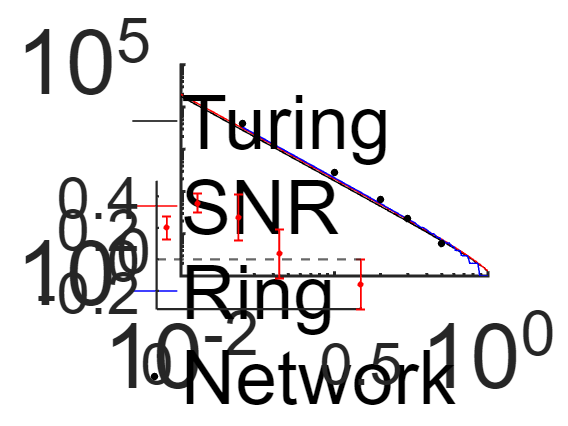

diff_cap = diff_cap2 ./ cap_saddle2;
mean_dif_cap = mean(diff_cap, 2);
var_dif_cap = var(diff_cap');
axes('Position',[.275 .275 .36 0.3])
errorbar(s_sim, mean_dif_cap, 1.96*sqrt(var_dif_cap), "r.", "LineStyle","none", "MarkerSize", 12, "LineWidth", 1.2)
yline(0, "--", "LineWidth", 1.5)
box off
xlim([0, 0.5])
set(gca, "FontSize", 40)
set(gca, "LineWidth", 1.5)
set(gca, 'Color', 'None')


%}

## Capacity as function of M for different cases

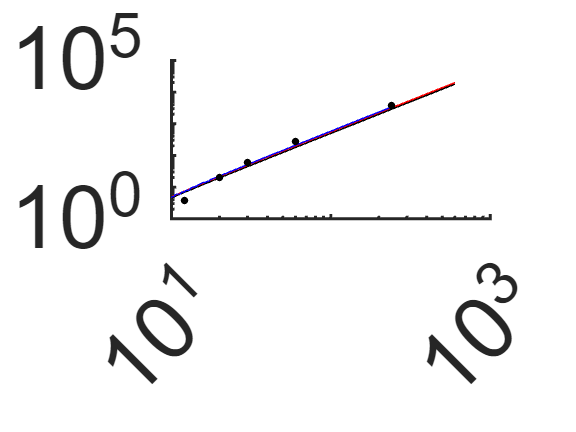

M_sim = 6./ s_sim;
M_seq2 = 6./s_seq2;

figure
loglog(M_seq, (cap_turing), "-k", "LineWidth", 1)
hold on
loglog(M_seq, (cap_SNR), "-r", "LineWidth", 1)
loglog(M_seq2, (cap_saddle), "-b", "LineWidth", 1)
loglog(M_sim, cap_network, ".k", "MarkerSize", 15)
hold off
axis tight
xlim([1e1, 1e3])
xticks([1e1, 1e2, 1e3])
xticklabels(["10^1", "", "10^3"])
ylim([1e0, 1e5])
yticks([1e0, 1e1, 1e2, 1e3, 1e4, 1e5])
yticklabels(["10^0", "", "", "", "", "10^5"])
box off
fig_config(50)
set(gca, "LineWidth", 2)

## Auxiliar Functions

function list_files = look_files_by_pattern(dir_name, patterns)    
    all_files = dir(dir_name);
    list_files = {all_files.name};
    for pattern = patterns
        list_files = list_files(contains(list_files, pattern));  
    end
end

function amp_res = compute_first_FFT(FR_results, phase, n_ca3_per_track)
    mean_FR = cellfun(@(x) grpstats(x', phase, {'mean'}), FR_results,'UniformOutput',false);
    amp_res = cell(length(mean_FR), 1);
    for i = 1:length(mean_FR)
        FR = mean_FR{i};
        f_fft = fft(FR', [], 2) / n_ca3_per_track;
        amp_i = 2 * abs(f_fft(:, 2));
        amp_res{i} = amp_i';
    end
end

function [w1_crit, w1_crit_ring, eta_crit] = find_w1_crit(P, D, M, s, w0, w_max, I0, n_ca3_per_track)
    r0 = (1 - 2*w0*I0 - sqrt(1 - 4*w0*I0)) ./ (2*w0.^2);
    w1_crit_ring = 1 ./(w0*r0+I0);
    
    is_stack = true;
    eta = 0;
    w1_aux = 999;
    while w1_aux > w1_crit_ring
        [~, ~, ~, amp, A, ~, C] = Compute_mean_variance(P, D, eta, is_stack, M, s, nan, w0, w_max);
        w1_aux = amp + sqrt(A + C/2) * sqrt(2*pi/(n_ca3_per_track));
        
        eta = eta + 0.1;
    end

    f = @(P, D, eta, s) 2*P*D./(P+D)*(1-s^2*(P+D)).^eta;
    w1_crit = w_max * f(P, D, eta, s);
    eta_crit = eta;
end

function [tau, d_t, err, check_dynamic, plot_mean, activation_all, tracker, max_step] = FR_sim_setup()
    % setup
    tau = 20;
    d_t = 0.5;
    err = 1e-12;
    
    check_dynamic = false;
    plot_mean = true;
    activation_all = false;
    tracker = false;
    max_step = nan;
end

function weight_ring = generate_ring_noise_weight(phase, w0, w_max, P, D, M, s, eta, get_noise, is_stack)
    phase = unique(phase);
    
    phase_matrix = phase - phase';
    %is_stack = true; 
    if nargin < 10
        is_stack = true;
    end
    [weight_ring, V] = Compute_mean_variance(P, D, eta, is_stack, M, s, phase_matrix, w0, w_max);

    if get_noise 
        rng(20221213)
        weight_ring = normrnd(weight_ring, 1*sqrt(V));
    end
end
